# Actividad #7

**Generación, Visualización y Almacenamiento de dinamico de Datasets CSV**

- Nombre:

- Fecha:

- Reposiroty: [https://github.com/vasanza/SSE](https://github.com/vasanza/SSE)

- Refrence: [https://github.com/vasanza/Matlab_Code/tree/main](https://github.com/vasanza/Matlab_Code/tree/main)

## Descripción:

## Objetivos:

- Generar y visualizar señales senoidales con diferentes parámetros.

- Organizar los datos en un arreglo tipo dataset combinando múltiples señales y **TimeStamp**.

- Exportar datos generados en MATLAB a un archivo **dataset.CSV** utilizando funciones personalizadas.

- Mantener una estructura de proyecto ordenada y respaldada usando carpetas y funciones (`src`, `git_sse`, `fSave_file`).

## **Copia la actividad en tu respaldo**

%Configuracion de carpeta ./src para librerias
addpath(genpath('./src'));

% Definir rutas
miRespaldo = 'C:\Desktop\SSE_vic';  %<========
repositorio = 'C:\Desktop\SSE\2025';%<========

if true
    % repositorio -> respaldo
    git_sse(miRespaldo)
else
    % Mombre de la carpeta de la Actividad en el repositorio
    nombreCarpeta = string(split(cd, filesep));
    nombreCarpeta = nombreCarpeta(end) % Nombre de la carpeta
    % Regresar al repositorio
    cd(fullfile(repositorio,nombreCarpeta))
end

  --- SEÑAL SENOIDAL ---
 function [y] = senal_senoidal(frecuencia,amplitud,fase,tiempo,fs)
 
  Parámetros:
  f = 10;         % Frecuencia en Hz
  A = 1;          % Amplitud
  fase1 = 0; fase2 = 10;        % Fase
  T = 1;          % Duración en segundos
  fs = 1000;      % Frecuencia de muestreo en Hz



## Desarrollo de la Actividad

#### **Paso 1: Borrar variables en el workspace y limpiar cmd**

clear % Borrar variables en el workspace y libera memoria RAM
clc % Limpia el Command Window
addpath(genpath('./src'));

#### **Paso 2: Crear un codigo basico**

% Parámetros
f = 10;         % Frecuencia de la señal en Hz

simulationTime = 1×1001 duration array
Columns 1 through 909

      0 sec   0.01 sec   0.02 sec   0.03 sec   0.04 sec   0.05 sec   0.06 sec   0.07 sec   0.08 sec   0.09 sec    0.1 sec   0.11 sec   0.12 sec   0.13 sec   0.14 sec   0.15 sec   0.16 sec   0.17 sec   0.18 sec   0.19 sec    0.2 sec   0.21 sec   0.22 sec   0.23 sec   0.24 sec   0.25 sec   0.26 sec   0.27 sec   0.28 sec   0.29 sec    0.3 sec   0.31 sec   0.32 sec   0.33 sec   0.34 sec   0.35 sec   0.36 sec   0.37 sec   0.38 sec   0.39 sec    0.4 sec   0.41 sec   0.42 sec   0.43 sec   0.44 sec   0.45 sec   0.46 sec   0.47 sec   0.48 sec   0.49 sec    0.5 sec   0.51 sec   0.52 sec   0.53 sec   0.54 sec   0.55 sec   0.56 sec   0.57 sec   0.58 sec   0.59 sec    0.6 sec   0.61 sec   0.62 sec   0.63 sec   0.64 sec   0.65 sec   0.66 sec   0.67 sec   0.68 sec   0.69 sec    0.7 sec   0.71 sec   0.72 sec   0.73 sec   0.74 sec   0.75 sec   0.76 sec   0.77 sec   0.78 sec   0.79 sec    0.8 sec   0.81 sec   0.82 sec   0.83 sec   0.84 sec   

A1 = 3;          % Amplitud1

startTime = datetime
   13-Jun-2025 20:17:42


A2 = 16;          % Amplitud1

timeStamp = 1001×1 datetime array
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42
   13-Jun-2025 20:17:42


fase1 = 0;      % Fase1

ans = 'dd-MMM-uuuu HH:mm:ss'

fase2 = 10;     % Fase2

ans =         1001           1


T = 10;          % Duración en segundos
fsmin = f*2;    % Frecuencia de muestreo minima (Nyquist-Shannon)
fs = 100;      % Frecuencia de muestreo en Hz

Documentacion de la senal senoidal

help senal_senoidal
% Usamos la funcion: senal_senoidal(frecuencia,amplitud,fase,tiempo,fs)
y1 = senal_senoidal(f,A1,fase1,T,fs)';
y2 = senal_senoidal(f,A2,fase2,T,fs)';
y3 = y1 + y2;

#### **Paso 3: TimeStamp (dd-MMM-yyyy HH:mm:ss)**

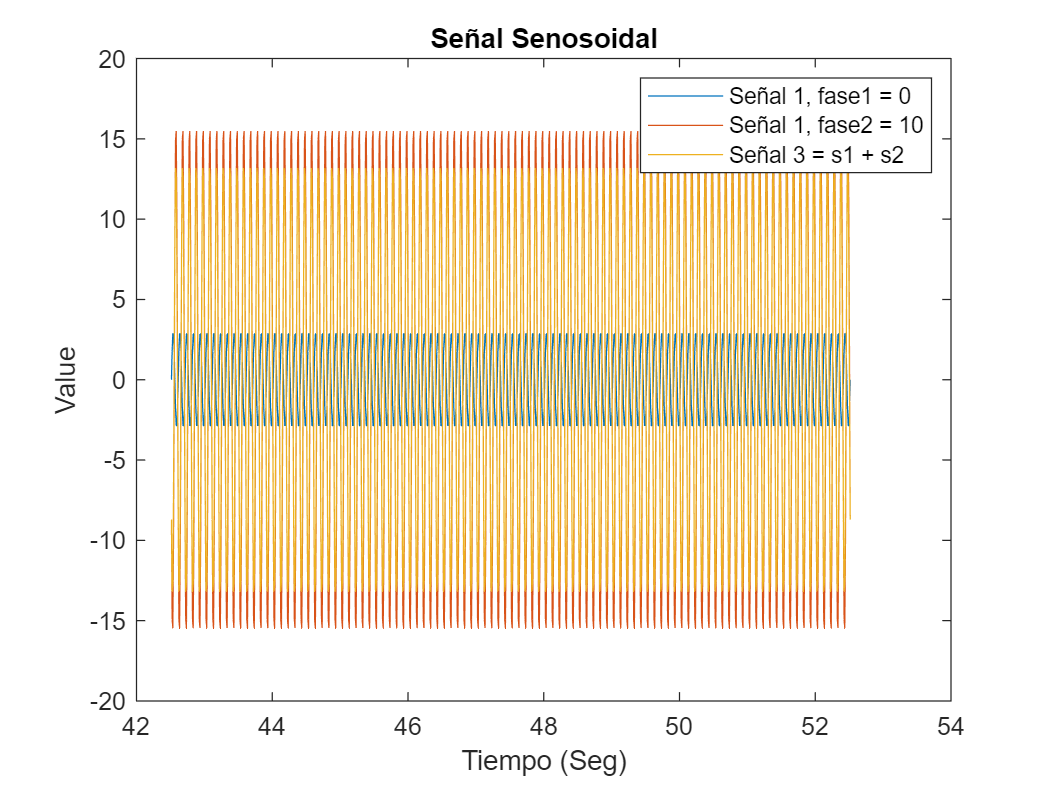

simulationTime = seconds(0:1/fs:T)
 startTime = datetime('now')
timeStamp = (startTime + simulationTime)'
timeStamp.Format

size(timeStamp) %filas, columnas

#### **Paso 4: Mostrar resultados con plot**

figure

VariableNames = 1×4 cell array
    {'TimeStamp'}    {'Sin1'}    {'Sin2'}    {'Sin1 + Sin2'}


plot(timeStamp.Second,y1) %Señal 1
hold on

dataset = 1001×4 table
         TimeStamp             Sin1          Sin2      Sin1 + Sin2
    ____________________    ___________    ________    ___________

    13-Jun-2025 20:17:42              0     -8.7043      -8.7043  
    13-Jun-2025 20:17:42         1.7634     -14.933       -13.17  
    13-Jun-2025 20:17:42         2.8532     -15.458      -12.605  
    13-Jun-2025 20:17:42         2.8532     -10.078      -7.2251  
    13-Jun-2025 20:17:42         1.7634    -0.84914      0.91421  
    13-Jun-2025 20:17:42     3.6739e-16      8.7043       8.7043  
    13-Jun-2025 20:17:42        -1.7634      14.933        13.17  
    13-Jun-2025 20:17:42        -2.8532      15.458       12.605  
    13-Jun-2025 20:17:42        -2.8532      10.078       7.2251  
    13-Jun-2025 20:17:42        -1.7634     0.84914     -0.91421  
    13-Jun-2025 20:17:42    -7.3479e

plot(timeStamp.Second,y2) %Señal 2

ans = 1×4 cell array
    {'TimeStamp'}    {'Sin1'}    {'Sin2'}    {'Sin1 + Sin2'}


plot(timeStamp.Second,y3) %Señal 3

ans = 1001

title("Señal Senosoidal")
xlabel("Tiempo (Seg)")
ylabel("Value")
legend("Señal 1, fase1 = 0", "Señal 1, fase2 = 10", "Señal 3 = s1 + s2")
hold off

#### **Paso 5: crear dataset usando tablas**

%cell array
VariableNames = {'TimeStamp', 'Sin1', 'Sin2', 'Sin1 + Sin2'}
% Para la tabla el timeStamp debe ser una columna
dataset = table(timeStamp, y1, y2, y3, 'VariableNames',VariableNames)
dataset.Properties.VariableNames
height(dataset)

#### Paso 6: Guardar los carchivos VSC en el computador

filename = 'dataset.csv';
fSave_dataset(filename,dataset)